r = randn(1,1000)';

% pendulum equations, no friction:
syms th(t) a
Dth = diff(th,t);
eqtn = diff(th,t,2) == -a*(th);
conds = [th(0) == pi/180*10, Dth(0) == 0];
sol(t) = simplify(dsolve(eqtn,conds));

g = 9.8; % m/s^2
l = 1; % m
m1 = 1; % kg
m2 = 2; % kg
a = 3*g/l*(m1/2 + m2)/(m1 + 3*m2);

sol(t) = simplify(subs(sol(t),sym('a'),a));

ts = 0.01;
t = 0:ts:10-ts;

theta = double(sol(t))';
dsol = diff(sol);
dtheta = double(dsol(t))';
sigma = pi/18/5;
theta_rand = double(theta + r*sigma);
sigma_d = 0.1; % sqrt(m/s) 
dtheta_rand = double(dtheta + r*sigma_d);

xr = l*cos(theta_rand); x = l*cos(theta);
yr = l*sin(theta_rand); y = l*sin(theta);

% plot(xr,yr,'*',x,y)
% plot(t,theta_rand,'*',t,theta)

writematrix([theta_rand, dtheta_rand],"data/theta_dtheta_rand.csv")
writematrix([theta, dtheta],"data/theta_dtheta.csv")
writematrix(t',"data/t.csv")

## Practice discretization from ECE6555 HW4

A = [0 0 1 0; 0 0 0 1; zeros(2,4)];
B = [0 0; 0 0; 1 0; 0 1];
T = sym('T');
syms t;
expm(A*T)

$$ans = \left(\begin{array}{cccc} 1 & 0 & T & 0\\ 0 & 1 & 0 & T\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


expm(A*T)*B

$$ans = \left(\begin{array}{cc} T & 0\\ 0 & T\\ 1 & 0\\ 0 & 1 \end{array}\right)$$

int(expm(A*(T-t))*B*transpose(expm(A*(T-t))*B),sym('t'),[0,T])

$$ans = \left(\begin{array}{cccc} \frac{T^{3}}{3} & 0 & \frac{T^{2}}{2} & 0\\ 0 & \frac{T^{3}}{3} & 0 & \frac{T^{2}}{2}\\ \frac{T^{2}}{2} & 0 & T & 0\\ 0 & \frac{T^{2}}{2} & 0 & T \end{array}\right)$$

## discretization of pendulum

% symbolically
syms a real
A = [0 1; a 0];
B = [0; 1];
syms T t;
simplify(expm(A*(T-t)))

$$ans = \left(\begin{array}{cc} \cosh\left(\sqrt{a}\,\left(T-t\right)\right) & \frac{\sinh\left(\sqrt{a}\,\left(T-t\right)\right)}{\sqrt{a}}\\ \sqrt{a}\,\sinh\left(\sqrt{a}\,\left(T-t\right)\right) & \cosh\left(\sqrt{a}\,\left(T-t\right)\right) \end{array}\right)$$

simplify(expm(A*(T-t))*transpose(expm(A*(T-t))))

$$ans = \begin{array}{l} \left(\begin{array}{cc} {\cosh\left(\sigma_{2}\right)}^{2}+\frac{{\sinh\left(\sigma_{2}\right)}^{2}}{a} & \sigma_{1}\\ \sigma_{1} & {\left(\frac{\sqrt{a}\,{\mathrm{e}}^{\sigma_{2}}}{2}-\frac{\sqrt{a}\,{\mathrm{e}}^{-\sigma_{2}}}{2}\right)}^{2}+{\left(\frac{{\mathrm{e}}^{\sigma_{2}}}{2}+\frac{{\mathrm{e}}^{-\sigma_{2}}}{2}\right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sinh\left(2\,\sqrt{a}\,\left(T-t\right)\right)\,\left(2\,a+2\right)}{4\,\sqrt{a}}\\ \sigma_{2}=\sqrt{a}\,\left(T-t\right) \end{array}$$

simplify(int(expm(A*(T-t))*B*transpose(expm(A*(T-t))*B),sym('t'),[0,T]))

$$ans = \left(\begin{array}{cc} \frac{\sinh\left(2\,T\,\sqrt{a}\right)}{4\,a^{3/2}}-\frac{T}{2\,a} & \frac{{\sinh\left(T\,\sqrt{a}\right)}^{2}}{2\,a}\\ \frac{{\sinh\left(T\,\sqrt{a}\right)}^{2}}{2\,a} & \frac{T}{2}+\frac{\sinh\left(2\,T\,\sqrt{a}\right)}{4\,\sqrt{a}} \end{array}\right)$$


% what does it look like with unit parameters? linearized around theta = 0
A = [0 1; -1 0];
B = [0; 1];
syms T t real
simplify(expm(A*(T-t)))

$$ans = \left(\begin{array}{cc} \cos\left(T-t\right) & \sin\left(T-t\right)\\ -\sin\left(T-t\right) & \cos\left(T-t\right) \end{array}\right)$$

simplify(expm(A*(T-t))*transpose(expm(A*(T-t))))

$$ans = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

simplify(int(expm(A*(T-t))*B*transpose(expm(A*(T-t))*B),sym('t'),[0,T]))

$$ans = \left(\begin{array}{cc} \frac{T}{2}-\frac{\sin\left(2\,T\right)}{4} & \frac{{\sin\left(T\right)}^{2}}{2}\\ \frac{{\sin\left(T\right)}^{2}}{2} & \frac{T}{2}+\frac{\sin\left(2\,T\right)}{4} \end{array}\right)$$


% with real numbers:
a = -3*g*(m1/2 + m2)/(l*(m1 + 3*m2));
qf = 3/(l^2*(m1 + 3*m2));
A = [0 1; a 0];
B = [0; 1];
syms T t;
N = 0.1; % N-m, power of process noise
q = qf^2*N;
Qk = simplify(q*int(expm(A*(T-t))*B*transpose(expm(A*(T-t))*B),sym('t'),[0,T]))

$$Qk = \begin{array}{l} \left(\begin{array}{cc} \frac{3\,T}{3430}-\frac{\sqrt{42}\,\sin\left(\sqrt{42}\,T\right)}{48020} & \sigma_{1}\\ \sigma_{1} & \frac{9\,T}{980}+\frac{3\,\sqrt{42}\,\sin\left(\sqrt{42}\,T\right)}{13720} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{3\,{\mathrm{e}}^{-\sqrt{42}\,T\,\mathrm{i}}\,{\left({\mathrm{e}}^{\sqrt{42}\,T\,\mathrm{i}}-1\right)}^{2}}{13720} \end{array}$$

Qk_real = real(double(subs(Qk,T,ts)))

Qk_real = 1.0e-03 *

    0.0000    0.0009
    0.0009    0.1836


## Discrete Time SS model

F = double(expm(A*ts))

F =     0.9995    0.0100
   -0.1050    0.9995


H = [1 0]

H =      1     0


G = eye(2)

G =      1     0
     0     1



rank(obsv(F,H)); % rank = 2; system is observable. 

R = sigma;
P = [sigma, 0; 0, sigma_d];

## Export Model data

writematrix(F,"data/A.csv");
writematrix(H,"data/H.csv");
writematrix(Qk_real,"data/Q.csv");
writematrix(R,"data/R.csv");
writematrix(P,"data/P.csv");
writematrix([theta_rand(1)*0.95, dtheta_rand(1) + max(dtheta_rand)*0.05],"data/xinit.csv")


## Filter the data

cd 'C:\Users\teowi\OneDrive\Documents\Assorted Files\Career_Work_Income\Georgia Tech\ECE6555 Optimal Estimation\kalman_filter_cpp'
system("x64\\Debug\\kalman_filter_cpp.exe")

ans = 0

## Plot filtered data

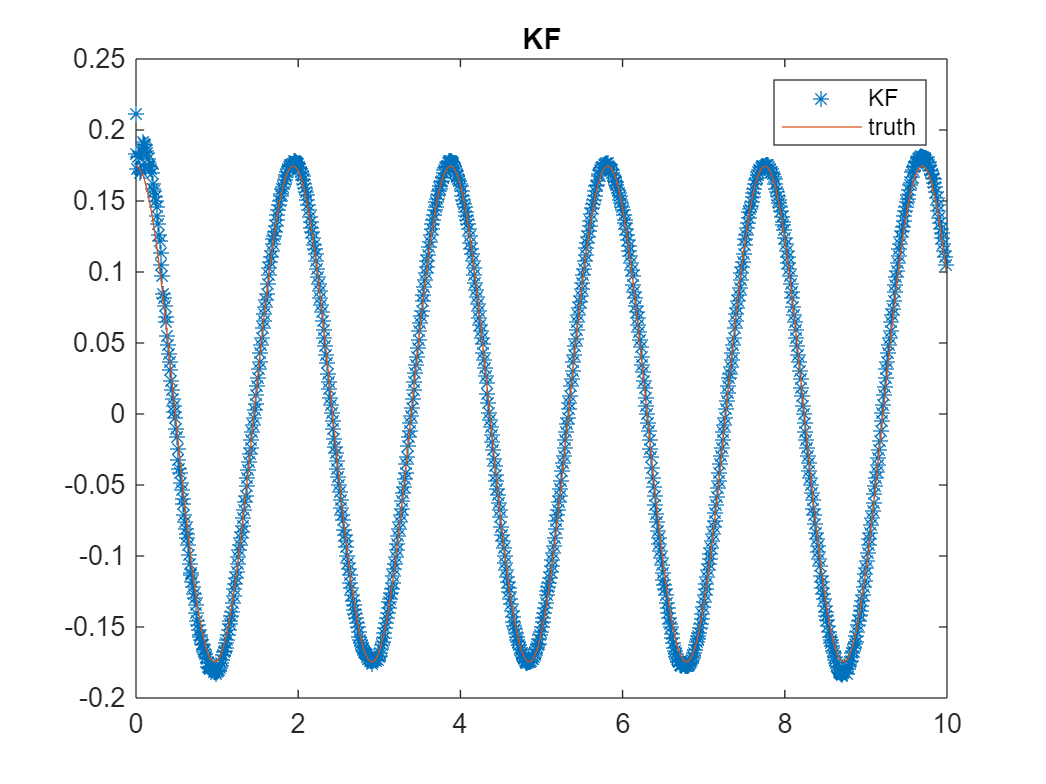

t = 0:ts:10-ts;
filtered = readmatrix("data/filtered_data.csv");
plot(t',filtered(:,1),'*',t',theta); title('KF');
legend('KF','truth');

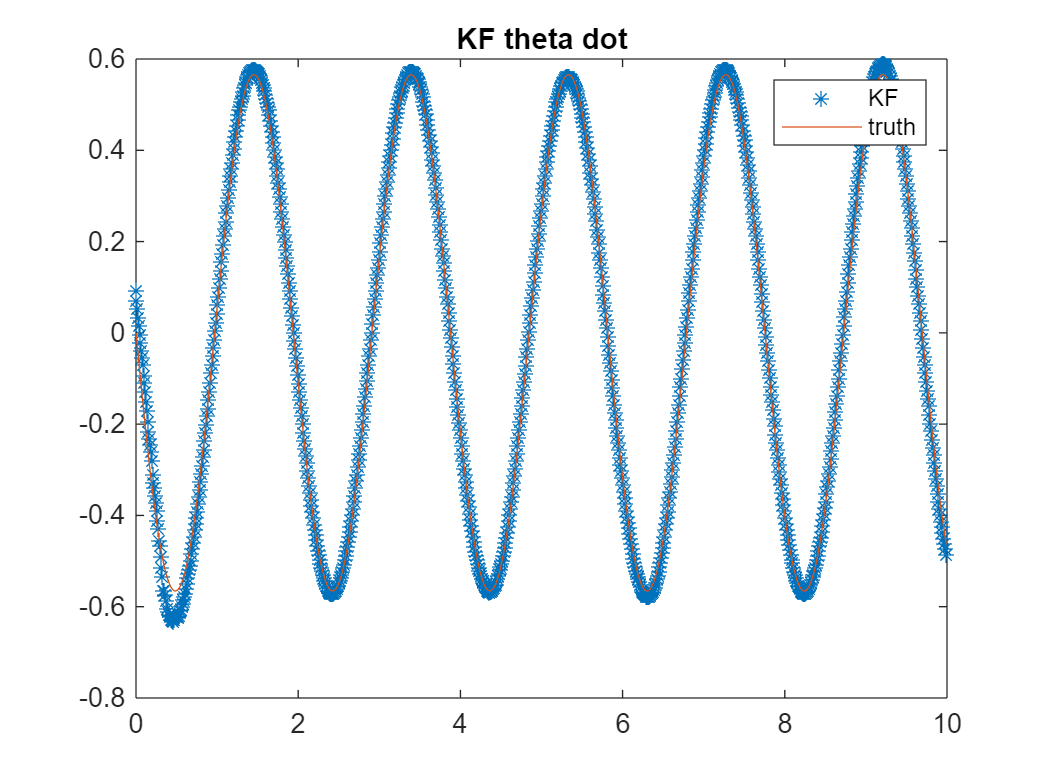

figure;
plot(t',filtered(:,2),'*',t',dtheta); title('KF theta dot')
legend('KF','truth');

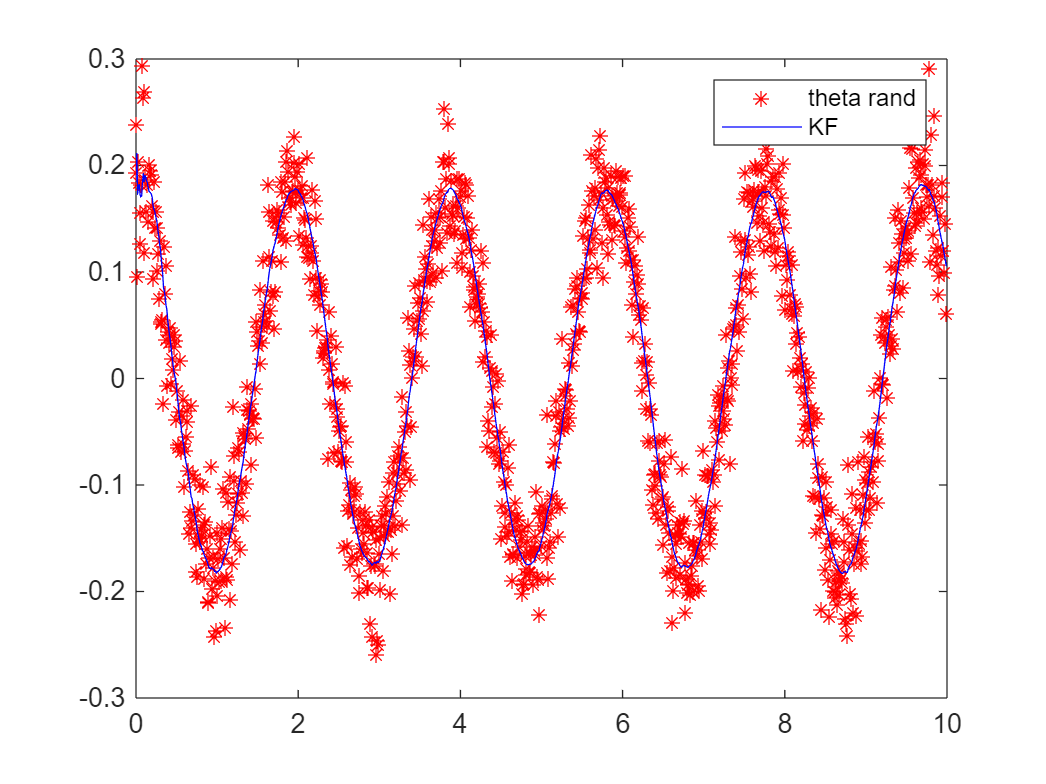

figure;
plot(t',theta_rand,'r*',t',filtered(:,1),'b');
legend('theta rand','KF')

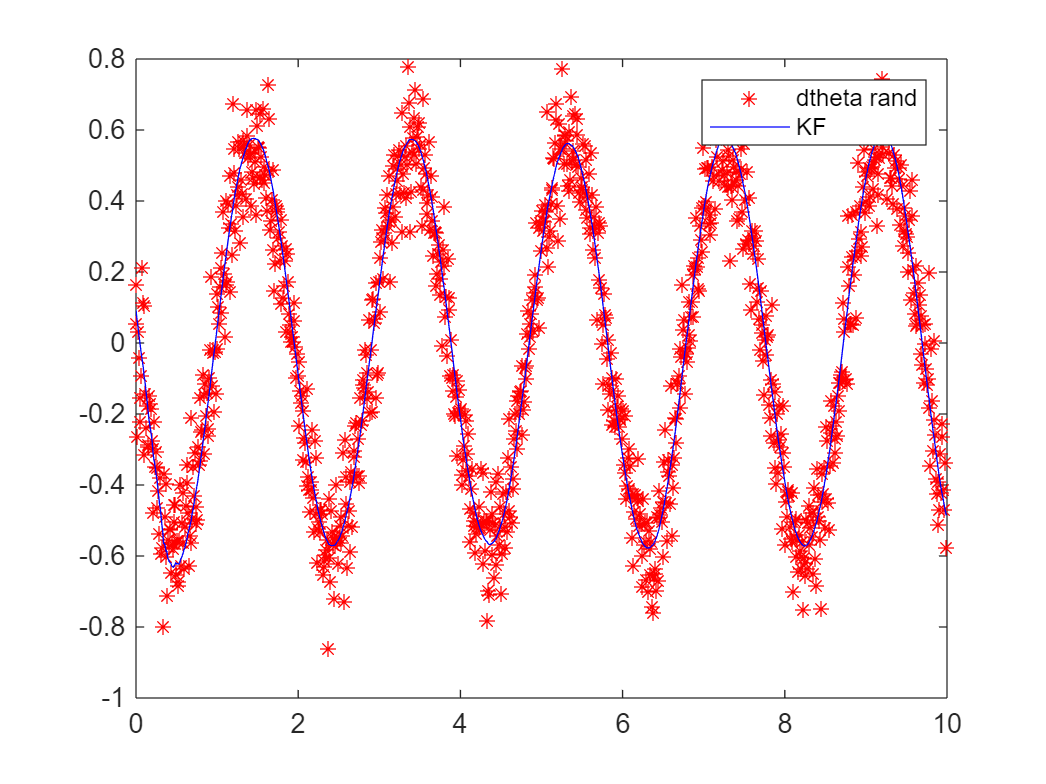

figure;
plot(t',dtheta_rand,'r*',t',filtered(:,2),'b');
legend('dtheta rand','KF')

## Generate Simulink data using MATLAB's KF block

cd 'C:\Users\teowi\OneDrive\Documents\Assorted Files\Career_Work_Income\Georgia Tech\ECE6555 Optimal Estimation\kalman_filter_cpp'
addpath(genpath('matlab'))
Kalman_Filter_Simulink_Example_params
sim("Kalman_Filter_Simulink_Example")

ts = 0.01;
F = double(expm(A*ts));
P = [Q, 0; 0, 0];
writematrix(F,"data/A.csv");
writematrix(C,"data/H.csv");
writematrix(diag([0,Q]),"data/Q.csv");
writematrix(R,"data/R.csv");
writematrix(P,"data/P.csv");
writematrix(xinit,"data/xinit.csv")

% write data for Cpp to filter:
writematrix([sim_meas.Data, sim_omega.Data],"data/theta_dtheta_rand.csv")


## Filter the Simulink data

system("x64\\Debug\\kalman_filter_cpp.exe")

ans = 0

## Plot filtered Simulink data vs. MATLAB's KF block

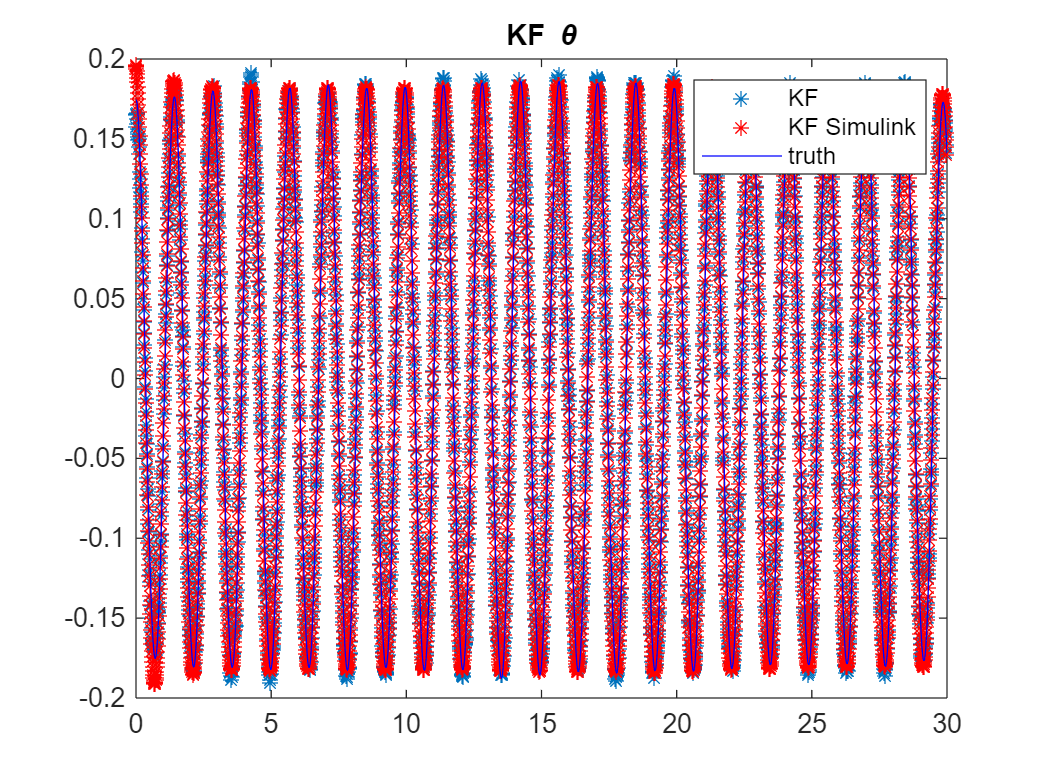

t = 0:ts:30;
filtered = readmatrix("data/filtered_data.csv");
plot(t',filtered(:,1),'*',tout,sim_est.Data(:,1),...
    'r*',tout,sim_theta.Data,'bl'); title('KF \theta');
legend('KF','KF Simulink','truth');

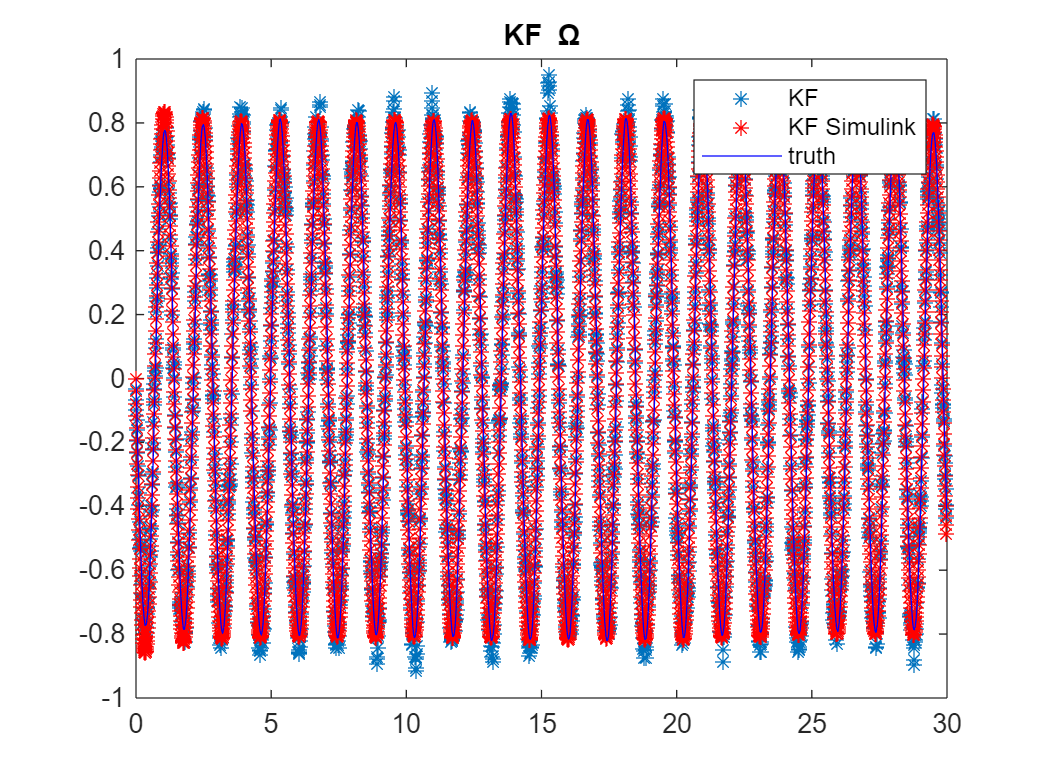

figure;
plot(t',filtered(:,2),'*',tout,sim_est.Data(:,2),...
    'r*',tout,sim_omega.Data,'bl'); title('KF \Omega');
legend('KF','KF Simulink','truth');

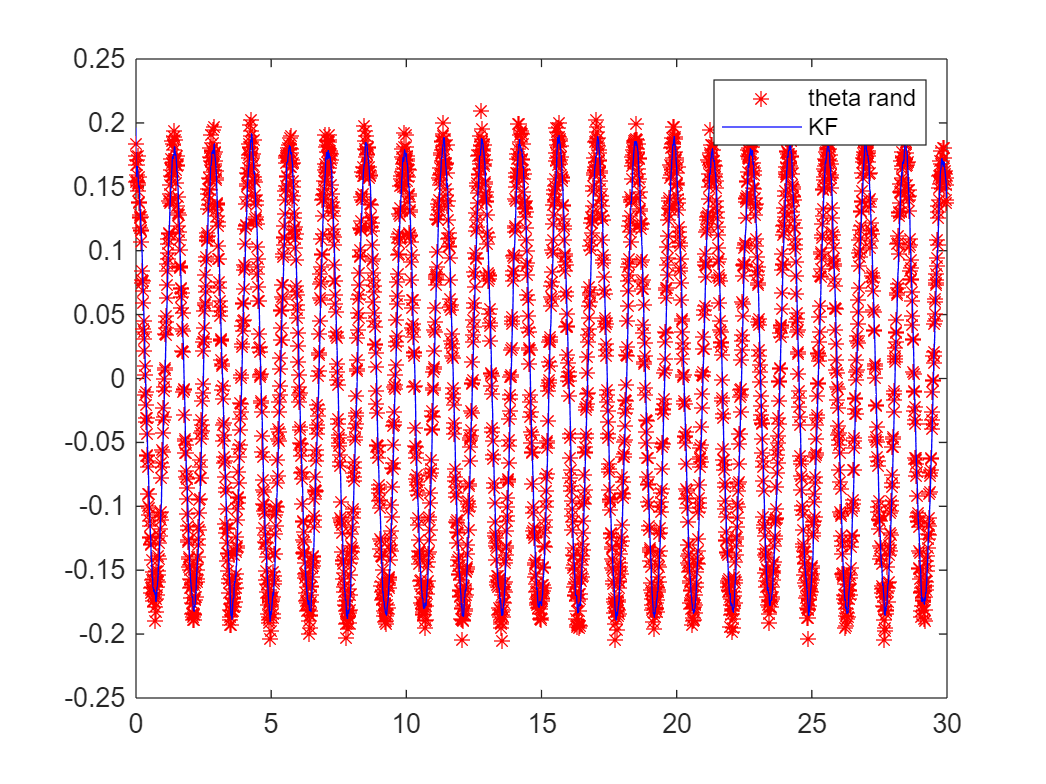

figure;
plot(tout,sim_meas.Data,'r*',t',filtered(:,1),'b');
legend('theta rand','KF')

## Compare MEA values between MATLAB and Custom KF

errKF = filtered(:,1) - sim_theta.Data;
errSimulink = sim_est.Data(:,1) - sim_theta.Data;
fprintf('MEA of custom KF is: %0.5f',mean(abs(errKF)))

MEA of custom KF is: 0.00326

fprintf('MEA of Simulink is: %0.5f',mean(abs(errSimulink)))

MEA of Simulink is: 0.00386

fprintf('Maximum theta of simulation: %0.3f radians', max(sim_theta.Data))

Maximum theta of simulation: 0.186 radians